This script is a part of the supplementary material for the following paper:

-  Jamshidi Idaji et al,  "Nonlinear Interaction Decomposition (NID): A Method for Separation of Cross-frequency Coupled Sources in Human Brain". doi: [https://doi.org/10.1016/j.neuroimage.2020.116599](https://doi.org/10.1016/j.neuroimage.2020.116599)

(C) Please cite the above paper in case of any significant usage of this script.

Corresponding Author: Vadim V. Nikulin (nikulin@cbs.mpg.de)

(C) Mina Jamshidi Idaji, Oct 2019, @ MPI CBS, Leipzig, Germany

jamshidi@cbs.mpg.de    .         minajamshidi91@gmail.com

https://github.com/minajamshidi/NID

# **Supplementary Code (4)**

# Realistic EEG Simulations: Dipole Orientations and Locations

In this script, we illustrate that in our simulation pipeline the dipoles are distributed randomely on the cortex and their orientations's azimuth and elevation has a uniform distribution.  

For this script, you will need the [METH toolbox](https://www.uke.de/english/departments-institutes/institutes/neurophysiology-and-pathophysiology/research/research-groups/index.html). 

Add the path of METH and our codes to your MATLAB.

%NID_dir = './NID_GitHub'; % you may add your own directory
%meth_dir = './meth/'; % you may add your own directory
addpath(genpath(meth_dir));
addpath(genpath(NID_dir));

First we load the head model:

load('sa_eeg.mat'); % the loaded structure is called sa

In the following, we have a part of our simulation pipeline, which produces the dipole orientations and positions. 

The orientaions (dipole_orient_3d) are produced by selecting a random point with radius 1 in the spherical coordinate system, i.e. the azimuth and elevation of the orientation vector are selected randomly from uniform distributions between $\left\lbrack -\pi ,\pi \right\rbrack$ and $\left\lbrack -\frac{\pi }{2},\frac{\pi }{2}\right\rbrack$ respectively.

The position of each dipole is selected as a random node among the nodes of the cortex.

Since in our simulations, we have 100 Monte Carlo runs, we do the same here, in order to see the distribution of selected dipole orientations and positions. Note that we produce two pairs of sources in each run.

SourceNum = 4;
NoiseNum = 125;
iterN = 100;
dipole_orient_sig = zeros(SourceNum*iterN, 3);
dipole_pos_sig = zeros(SourceNum*iterN, 3);

[~, NoiseNum] = ...
    noise_dipoles_position(sa, NoiseNum);
dipole_orient_noise = zeros(NoiseNum*iterN, 3);
dipole_pos_noise = zeros(NoiseNum*iterN, 3);

for k = 1:iterN
    rng('shuffle');
    theta = rand(NoiseNum+SourceNum, 1);
    theta = theta*2*pi - pi;
    phi = rand(NoiseNum+SourceNum, 1);
    phi = phi*pi - pi/2;
    [X, Y, Z] = sph2cart(theta, phi, ones(NoiseNum+SourceNum, 1));    
    dipole_orient_3d = [X, Y, Z];
    
    dipole_orient_sig((k-1)*SourceNum+1:k*SourceNum, :) = ...
        dipole_orient_3d(1:SourceNum,:);
    dipole_orient_noise((k-1)*NoiseNum+1:k*NoiseNum, :) = ...
        dipole_orient_3d(SourceNum+1:SourceNum+NoiseNum,:);
   
    %% generate random dipole positions for synced sources and noise
    
    dipole_idx = randperm(size(sa.cortex.vc,1));
    
    dipole_pos_sig((k-1)*SourceNum+1:k*SourceNum, :) = ...
        sa.cortex.vc(dipole_idx(1:SourceNum),:);
    
    [dipole_pos_noise((k-1)*NoiseNum+1:k*NoiseNum, :), ~] = ...
    noise_dipoles_position(sa, 125);
    
end

Now, we can plot the dipoles on the cortex:

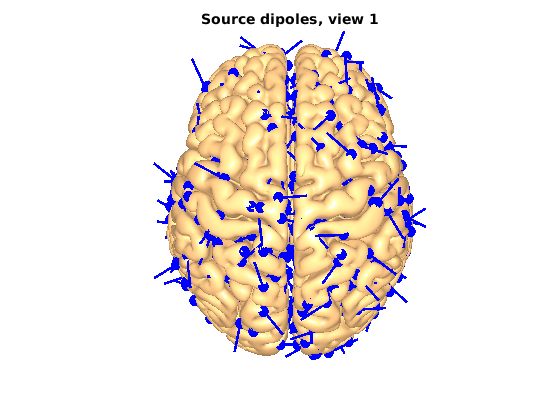

vc1 = struct;
vc1.tri = sa.cortex.tri;
vc1.vc = sa.cortex.vc;
para.myviewdir = [0, 0, 0.5];
figure, showsurface(vc1, para, [dipole_pos_sig, dipole_orient_sig]);
title('Source dipoles, view 1')

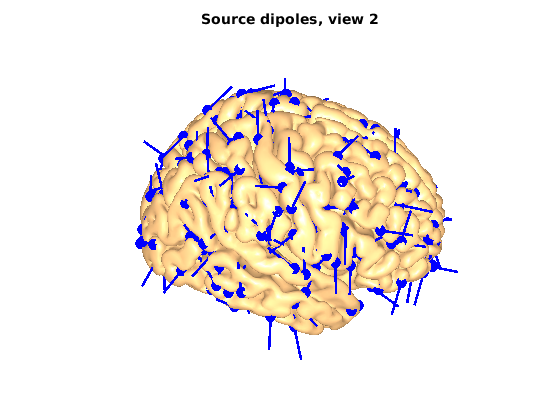


para.myviewdir = [1, 0, 0.5];
figure, showsurface(vc1, para, [dipole_pos_sig, dipole_orient_sig]);
title('Source dipoles, view 2')

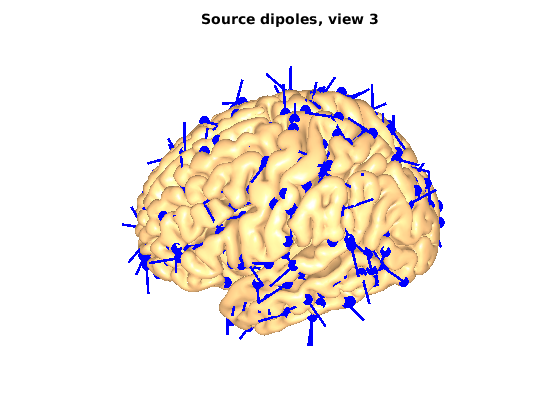


para.myviewdir = [-1, 0, 0.5];
figure, showsurface(vc1, para, [dipole_pos_sig, dipole_orient_sig]);
title('Source dipoles, view 3')

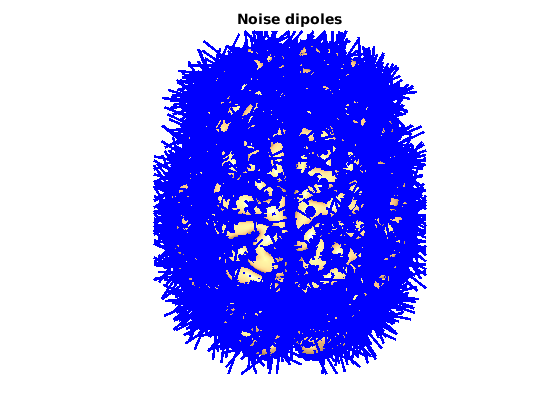


para.myviewdir = [0, 0, 0.5];
figure, showsurface(vc1, para, [dipole_pos_noise, dipole_orient_noise]);
title('Noise dipoles')

The figures show that the dipoles are distributed evenly on the cortex and there is no specific orientation for them. To quantify the distribution of the orientations, let's look at the histogram of the azimuth and elevation of the orientations in the spherical coordinate system:

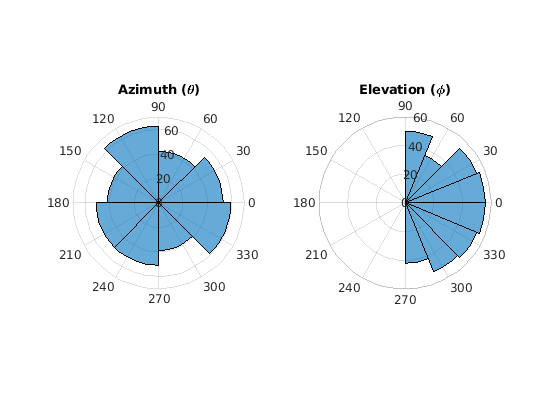

[dip_ori_th, dip_ori_phi, dip_ori_R] = ...
    cart2sph(dipole_orient_sig(:,1), dipole_orient_sig(:,2), ...
    dipole_orient_sig(:,3));
figure,  
subplot(1,2,1),
polarhistogram(dip_ori_th)
title('Azimuth (\theta)')
subplot(1,2,2) , 
polarhistogram(dip_ori_phi)
title('Elevation (\phi)')

As expected by the implementation, the distributions of the azimuth and the elevation are uniform.

Now let's look at the distribution of dipoles locations. From the figures above (brains with source dipoles), we can guess that the dipoles are homogeneously distributed on the cortex. Here we check it numerically:

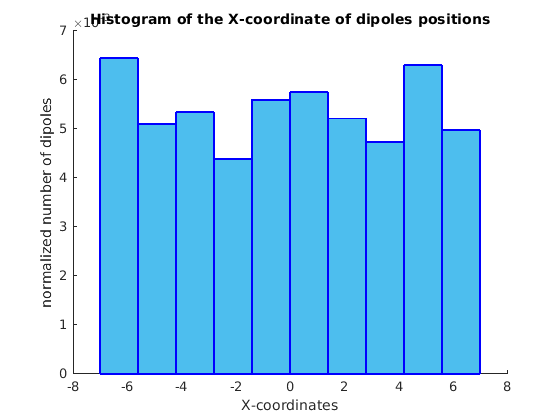

[BinValues, BinEdges] = histcounts(dipole_pos_sig(:,1), 10);
BinValues = normalize_BinValues(BinEdges, BinValues, vc1.vc(:,1));
figure, plot_barplot(BinEdges, BinValues)
title('Histogram of the X-coordinate of dipoles positions');
xlabel('X-coordinates')
ylabel('normalized number of dipoles')

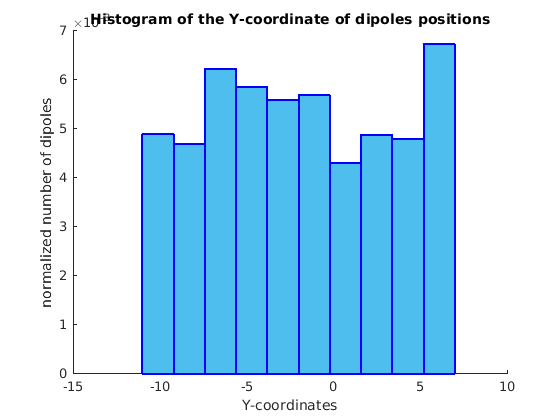


[BinValues, BinEdges] = histcounts(dipole_pos_sig(:,2), 10);
BinValues = normalize_BinValues(BinEdges, BinValues, vc1.vc(:,2));
figure, plot_barplot(BinEdges, BinValues)
title('Histogram of the Y-coordinate of dipoles positions')
xlabel('Y-coordinates')
ylabel('normalized number of dipoles')

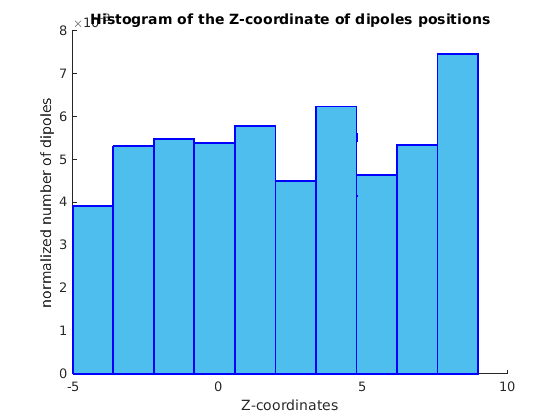


[BinValues, BinEdges] = histcounts(dipole_pos_sig(:,3), 10);
BinValues = normalize_BinValues(BinEdges, BinValues, vc1.vc(:,3));
figure, plot_barplot(BinEdges, BinValues)
title('Histogram of the Z-coordinate of dipoles positions')
xlabel('Z-coordinates')
ylabel('normalized number of dipoles')

## Conclusion

- With this script, we emphasize that there is no bias in the selection of the position and orientation of the dipoles; and that we select them randomely.

- We showed that the dipole positions and orientatitons are distributed in the space homogeneously.

## Functions

A function for selecting noise dipoles from a NxNxN grid on cortex: 

function [dipole_pos_3d_noise, N_dipoles_f] = ...
    noise_dipoles_position(source_analysis, N_dipoles)
N = ceil(nthroot(N_dipoles,3));
vc = source_analysis.cortex.vc;
vc_x = vc(:,1);
vc_y = vc(:,2);
vc_z = vc(:,3);
% x_range = max(vc_x) - min(vc_x);
x_bins = linspace(min(vc_x)-0.1,  max(vc_x)+0.1, N+1);
y_bins = linspace(min(vc_y)-0.1,  max(vc_y)+0.1, N+1);
z_bins = linspace(min(vc_z)-0.1,  max(vc_z)+0.1, N+1);
n = 0;
dipole_pos_3d_noise = NaN(N^3,3);
for ix = 1:N
    for iy = 1:N
        for iz = 1:N
            n = n + 1;
            IND = vc_x>=x_bins(ix) & vc_x<x_bins(ix+1) & ...
                vc_y>=y_bins(iy) & vc_y<y_bins(iy+1) & ...
                vc_z>=z_bins(iz) & vc_z<z_bins(iz+1);
            if ~sum(IND)
                dipole_pos_3d_noise(n,:) = [];
                n = n - 1;
            else
                vc_ind = vc(IND,:);
                idx_vox = randi(sum(IND), 1);
                dipole_pos_3d_noise(n, :) = vc_ind(idx_vox,:);
            end
            
        end
    end
end
N_dipoles_f = size(dipole_pos_3d_noise, 1);
end

A function for normalizing the bin values of dipole positions: here the number of dipoles in each bin is normallized by the total number of voxels with the coordinate of that bin:

function BinValue = normalize_BinValues(BinEdges, BinValue, vc)
BinEdges(end) = BinEdges(end) + 0.01;
for k = 1:length(BinValue)
    B1 = BinEdges(k);
    B2 =  BinEdges(k+1);
    n_vox = sum(vc>=B1 & vc<B2);
    BinValue(k) = BinValue(k)/n_vox;      
end
end

A function forplotting bar plots:

function plot_barplot(BinEdges, BinValues)
for k = 1:length(BinValues)
    B1 = BinEdges(k);
    B2 =  BinEdges(k+1);
    rectangle('Position', [B1, 0, B2-B1, BinValues(k)],...
        'Curvature',0.2,'FaceColor',[0.3010 0.7450 0.9330],'EdgeColor','b',...
    'LineWidth',1.5)
end
end

**Notification: **

THIS SOFTWARE IS PROVIDED BY THE COPYRIGHT HOLDERS AND CONTRIBUTORS "AS IS" AND ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, BUT NOT LIMITED TO, THE IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE ARE DISCLAIMED. IN NO EVENT SHALL THE COPYRIGHT HOLDER OR CONTRIBUTORS BE LIABLE FOR ANY DIRECT, INDIRECT, INCIDENTAL, SPECIAL, EXEMPLARY, OR CONSEQUENTIAL DAMAGES (INCLUDING, BUT NOT LIMITED TO, PROCUREMENT OF SUBSTITUTE GOODS OR SERVICES; LOSS OF USE, DATA, OR PROFITS; OR BUSINESS INTERRUPTION) HOWEVER CAUSED AND ON ANY THEORY OF LIABILITY, WHETHER IN CONTRACT, STRICT LIABILITY, OR TORT (INCLUDING NEGLIGENCE OR OTHERWISE) ARISING IN ANY WAY OUT OF THE USE OF THIS SOFTWARE, EVEN IF ADVISED OF THE POSSIBILITY OF SUCH DAMAGE.